# Potential field path-planning

## n.24  2018

clear all
close all
clc

format short
syms x y;

goal = [2; 0];
obstacle = [2.5; 0];
pose = [x; y];


rho_goal = sqrt((pose(1)-goal(1))^2+(pose(2)-goal(2))^2);
rho_obs = sqrt((pose(1)-obstacle(1))^2+(pose(2)-obstacle(2))^2);

% Attractive potential goal field:
U_attr = rho_goal^2;  %% Check with or without the 1/2 at the beginning

% Attractive force of the goal:
gradient_attr = [diff(U_attr,x); diff(U_attr,y)];
F_attr = -gradient_attr;

% Repulsive potential field of the obstacle:
U_rep = ((1/rho_obs)^2);

% Repulsive force of the obstacle:
gradient_rep = [diff(U_rep,x); diff(U_rep,y)];
F_rep = -gradient_rep;

[x,y]=vpasolve(0 == F_attr+F_rep ,[x,y])

$$x = \left(\begin{array}{c} 2.5\\ 1.3472234192816919730288219868694\\ 3.3949754886347408618986346576898\\ 2.3789005460417835825362716777204+0.97703764661540633684522977794253\,\mathrm{i}\\ 2.3789005460417835825362716777204-0.97703764661540633684522977794253\,\mathrm{i} \end{array}\right)$$

$$y = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

disp("--------------------------------------------------")

--------------------------------------------------


## n.18  2019

clear all
close all
clc

format short
syms x y;

goal = [2; 0];
obstacle = [2.6; 0];
pose = [x; y];


rho_goal = sqrt((pose(1)-goal(1))^2+(pose(2)-goal(2))^2);
rho_obs = sqrt((pose(1)-obstacle(1))^2+(pose(2)-obstacle(2))^2);

% Attractive potential goal field:
U_attr = (rho_goal^2);

% Attractive force of the goal:
gradient_attr = [diff(U_attr,x); diff(U_attr,y)];
F_attr = -gradient_attr;

% Repulsive potential field of the obstacle:
U_rep = (1/2)*((1/rho_obs-2)^2); %% Check with or without the 1/2 at the beginning

% Repulsive force of the obstacle:
gradient_rep = [diff(U_rep,x); diff(U_rep,y)];
F_rep = -gradient_rep;

[x,y]=vpasolve(0 == F_attr+F_rep ,[x,y])

$$x = 2.0881773317662216037121001291239$$

$$y = 0$$

disp("--------------------------------------------------")

--------------------------------------------------


## n.18  2021

clear all
close all
clc

format short
syms x y;

goal = [2; 0];
obstacle = [1; 0.3];
pose = [x; y];


rho_goal = sqrt((pose(1)-goal(1))^2+(pose(2)-goal(2))^2);

$$rho\_goal = \sqrt{{\left(x-2\right)}^{2}+y^{2}}$$

rho_obs = sqrt((pose(1)-obstacle(1))^2+(pose(2)-obstacle(2))^2);

$$rho\_obs = \sqrt{{\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}}$$


% Attractive potential goal field:
U_attr = (1/2)*(rho_goal^2);

$$U\_attr = \frac{{\left(x-2\right)}^{2}}{2}+\frac{y^{2}}{2}$$


% Attractive force of the goal:
gradient_attr = [diff(U_attr,x); diff(U_attr,y)];

$$gradient\_attr = \left(\begin{array}{c} x-2\\ y \end{array}\right)$$

F_attr = -gradient_attr;

$$F\_attr = \left(\begin{array}{c} 2-x\\ -y \end{array}\right)$$


% Repulsive potential field of the obstacle:
U_rep = (1/2)*((1/rho_obs-2)^2); %% Check with or without the 1/2 at the beginning

$$U\_rep = \frac{{\left(\frac{1}{\sqrt{{\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}}}-2\right)}^{2}}{2}$$


% Repulsive force of the obstacle:
gradient_rep = [diff(U_rep,x); diff(U_rep,y)]

$$gradient\_rep = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(2\,x-2\right)\,\sigma_{2}}{\sigma_{1}}\\ -\frac{\left(2\,y-\frac{3}{5}\right)\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\left({\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}\right)}^{3/2}\\ \sigma_{2}=\frac{1}{\sqrt{{\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}}}-2 \end{array}$$

F_rep = -gradient_rep

$$F\_rep = \begin{array}{l} \left(\begin{array}{c} \frac{\left(2\,x-2\right)\,\sigma_{2}}{\sigma_{1}}\\ \frac{\left(2\,y-\frac{3}{5}\right)\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\left({\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}\right)}^{3/2}\\ \sigma_{2}=\frac{1}{\sqrt{{\left(x-1\right)}^{2}+{\left(y-\frac{3}{10}\right)}^{2}}}-2 \end{array}$$

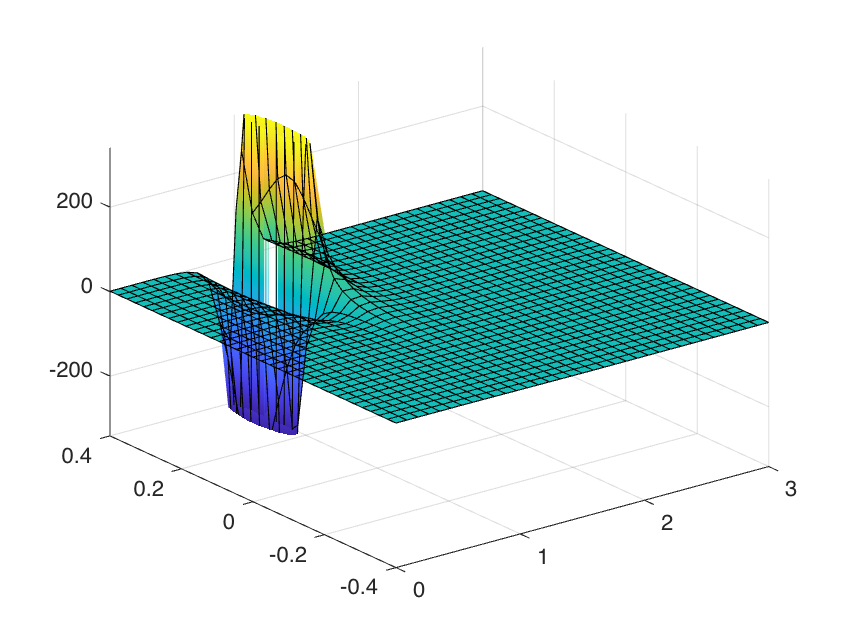

figure(1)
xlabel("x")
fsurf(F_rep(1))
xlim([0 3])
ylim([-0.4 0.4])


[x,y]=vpasolve(0 == F_attr+F_rep ,[x,y])

$$x = 1.5168727991155392027750477307179$$

$$y = 0.14493816026533823916748568078464$$

disp("--------------------------------------------------")

--------------------------------------------------
